T = 1:400;
N = 10;
tmin = 25;
t0 = 1;
u = binrand(T, N, tmin, t0, 'normal');

x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


% Define the transfer functions
numerator = [1, 0];
denominator = [10, -10];
ts = 0.01;
C = tf(numerator, denominator, ts);

num = [0.1812];
den = [1, -0.8187];
G = tf(num, den, ts);

variance1 = 0.1; % also for 0.01 and 0.001
variance2 = 0.01;
variance3 = 0.001;
noise1 = sqrt(variance1) * randn(size(u));
noise2 = sqrt(variance2) * randn(size(u));
noise3 = sqrt(variance3) * randn(size(u));

Ts = 0.01;                % Sample time of the models
N = length(u); 
timeVector = 0:Ts:(N-1)*Ts;

output1 = lsim((G*C)/(1+(G*C)), u.', timeVector.') + lsim(1/(1+C*G), noise1.', timeVector.');
output2 = lsim((G*C)/(1+(G*C)), u.', timeVector.') + lsim(1/(1+C*G), noise2.', timeVector.');
output3 = lsim((G*C)/(1+(G*C)), u.', timeVector.') + lsim(1/(1+C*G), noise3.', timeVector.');

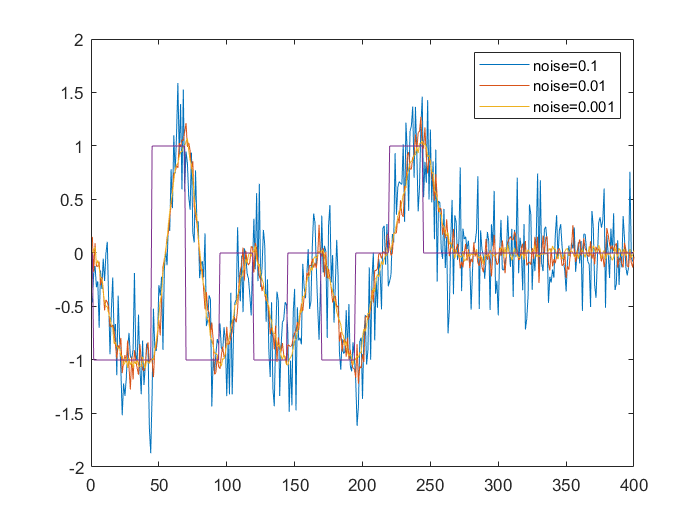

figure;
plot(output1)
hold on
plot(output2)
plot(output3)
plot(u)
legend('noise=0.1','noise=0.01', 'noise=0.001');
hold off

pairs1 = table(u.', output1, 'VariableNames', {'Input', 'Output'});
pairs2 = table(u.', output2, 'VariableNames', {'Input', 'Output'});
pairs3 = table(u.', output3, 'VariableNames', {'Input', 'Output'});

% Define a range of values for na, nb, and nk
% Parameters
na_values = [1, 2, 3 ,4 ];  % List of 'na' values to test
nc_values = [1, 2, 3 ,4];  % List of 'na' values to test
nb_values = [1, 2, 3 ,4 ];  % List of 'nb' values to test
nf_values = [1, 2, 3 ,4];  % List of 'na' values to test
nd_values = [1, 2, 3 ,4];  % List of 'na' values to test
nk_values = [0, 1, 2, 3 ,4];  % List of 'nk' values to test
best_na = 0;            % Variable to store the best 'na' value
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model

% OE with 0.1 noise
best_y_pred = [];  

% Loop over each combination of 'nb', 'nf', and 'nk' values
for nb = nb_values
    for nf = nf_values
        for nk = nk_values
            % Output-Error Model Identification
            sys = oe(iddata(output1, u.', 0.01), [nb, nf, nk]);
            sys.Ts = 0.01; 
            y_val_pred = compare(sys, iddata(output1, u.', 0.01));
            val_error = mean((y_val_pred.OutputData - output1).^2);
            if val_error < best_val_error
                best_val_error = val_error;
                best_nb = nb;
                best_nf = nf;
                best_nk = nk;
                best_model = sys;  % Store the best model
                best_y_pred = y_val_pred.OutputData;  
            end
        end
    end
end

% Display the best parameter values and validation error
disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 4


disp(['Best nf value: ', num2str(best_nf)]);

Best nf value: 4


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 2


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.10898



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: 1
                 B: [0 0 0.0911 -0.0094 -0.0440 0.0277]
                 C: 1
                 D: 1
                 F: [1 0.1367 -1.7202 -0.1753 0.8253]
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 0.1126
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



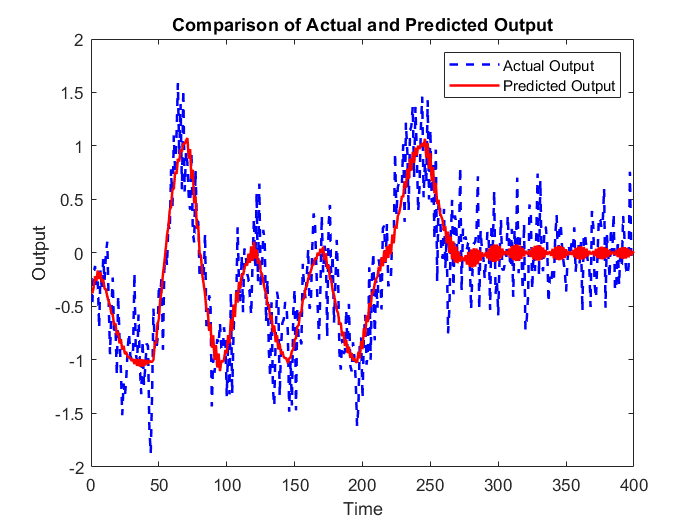

% Plot the actual output and predicted output
figure;
t = 1:length(output1);
plot(t, output1, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)              
  B(z) = 0.09107 z^-2 - 0.009431 z^-3 - 0.04403 z^-4 + 0.02772 z^-5
                                                                   
  F(z) = 1 + 0.1367 z^-1 - 1.72 z^-2 - 0.1753 z^-3 + 0.8253 z^-4   
                                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   nb=4   nf=4   nk=2
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                
Estimated using OE on time domain data.
Fit to estimation data: 46.51%         
FPE: 0.1148, MSE: 0.1103               


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

  -0.8639 + 0.0000i
   0.4837 + 0.3440i
   0.4837 - 0.3440i



disp('Poles:');

Poles:


disp(poles_est);

  -0.9761 + 0.1971i
  -0.9761 - 0.1971i
   0.9077 + 0.0913i
   0.9077 - 0.0913i



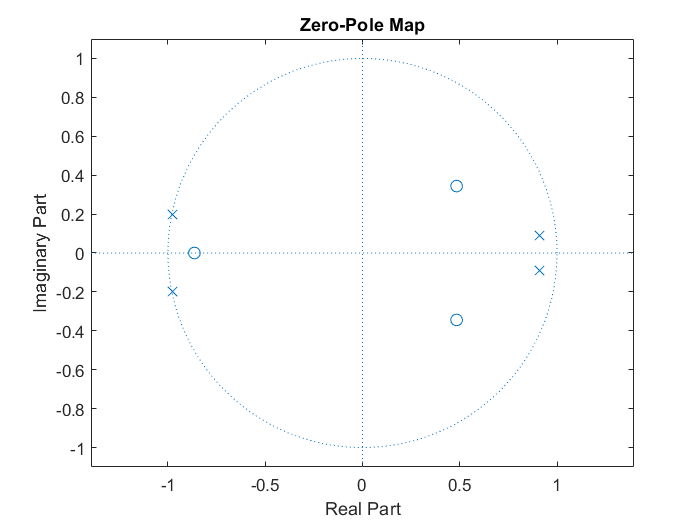


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.6256



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

   -0.3434



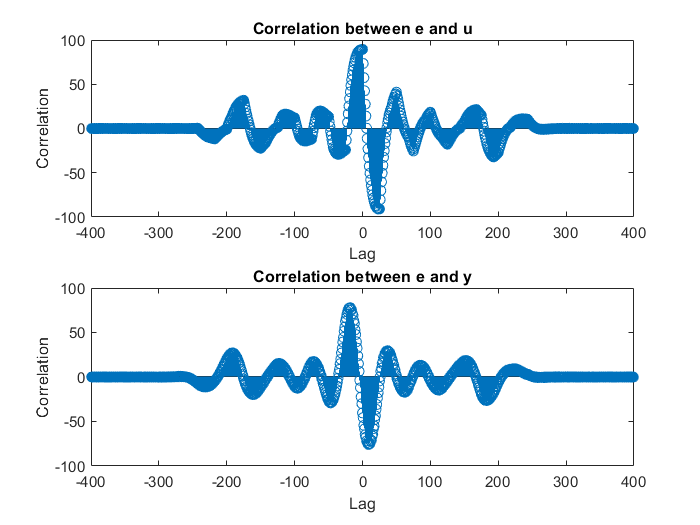


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');

% ARX with 0.01 noise
best_y_pred = [];  
best_na = 0;            % Variable to store the best 'na' value
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model
% Loop over each combination of 'nb', 'nf', and 'nk' values
for nb = nb_values
    for nf = nf_values
        for nk = nk_values
            % Output-Error Model Identification
            sys = oe(iddata(output2, u.', 0.01), [nb, nf, nk]);
            sys.Ts = 0.01; 
            y_val_pred = compare(sys, iddata(output2, u.', 0.01));
            val_error = mean((y_val_pred.OutputData - output2).^2);
            if val_error < best_val_error
                best_val_error = val_error;
                best_nb = nb;
                best_nf = nf;
                best_nk = nk;
                best_model = sys;  % Store the best model
                best_y_pred = y_val_pred.OutputData;  
            end
        end
    end
end

% Display the best parameter values and validation error
disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 4


disp(['Best nf value: ', num2str(best_nf)]);

Best nf value: 4


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 0


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.01017



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: 1
                 B: [0.0143 -0.0151 0.0353 0.0149]
                 C: 1
                 D: 1
                 F: [1 -0.6709 -0.7651 0.1289 0.3559]
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 0.0106
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



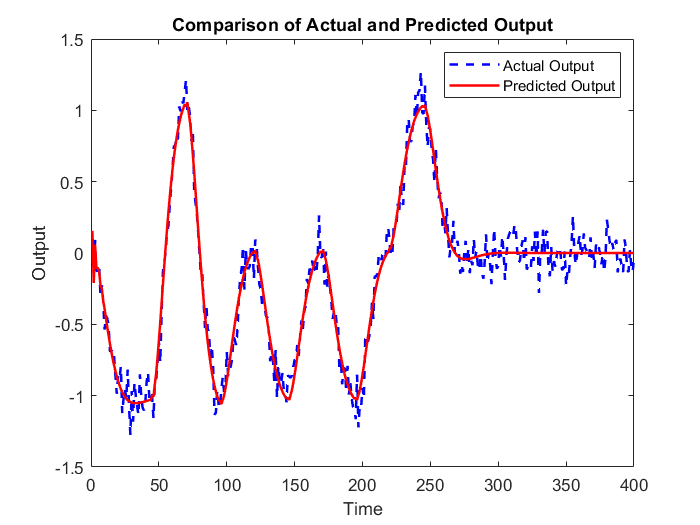

% Plot the actual output and predicted output
figure;
t = 1:length(output2);
plot(t, output2, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)             
  B(z) = 0.0143 - 0.01514 z^-1 + 0.03527 z^-2 + 0.01493 z^-3      
                                                                  
  F(z) = 1 - 0.6709 z^-1 - 0.7651 z^-2 + 0.1289 z^-3 + 0.3559 z^-4
                                                                  
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   nb=4   nf=4   nk=0
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                
Estimated using OE on time domain data.
Fit to estimation data: 81.3%          
FPE: 0.01077, MSE: 0.01035             


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

   0.0000 + 0.0000i
   0.7055 + 1.5701i
   0.7055 - 1.5701i
  -0.3523 + 0.0000i



disp('Poles:');

Poles:


disp(poles_est);

   0.8972 + 0.0921i
   0.8972 - 0.0921i
  -0.5618 + 0.3492i
  -0.5618 - 0.3492i



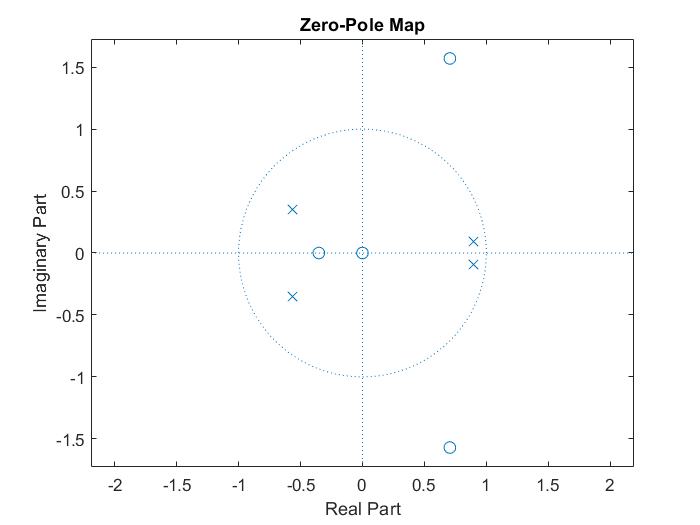


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.6038



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

   -0.3571



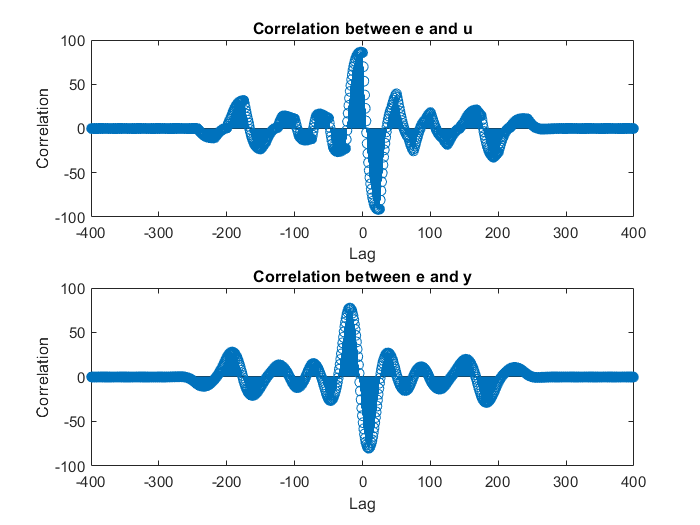


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');

% ARX with 0.01 noise
best_y_pred = [];  
best_na = 0;            % Variable to store the best 'na' value
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model
% Loop over each combination of 'nb', 'nf', and 'nk' values
for nb = nb_values
    for nf = nf_values
        for nk = nk_values
            % Output-Error Model Identification
            sys = oe(iddata(output3, u.', 0.01), [nb, nf, nk]);
            sys.Ts = 0.01; 
            y_val_pred = compare(sys, iddata(output3, u.', 0.01));
            val_error = mean((y_val_pred.OutputData - output3).^2);
            if val_error < best_val_error
                best_val_error = val_error;
                best_nb = nb;
                best_nf = nf;
                best_nk = nk;
                best_model = sys;  % Store the best model
                best_y_pred = y_val_pred.OutputData;  
            end
        end
    end
end

% Display the best parameter values and validation error
disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 4


disp(['Best nf value: ', num2str(best_nf)]);

Best nf value: 4


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 2


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.0009521



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: 1
                 B: [0 0 0.0637 -0.0233 -0.0043 0.0090]
                 C: 1
                 D: 1
                 F: [1 -1.0514 0.2205 -0.7406 0.6166]
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 9.8830e-04
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



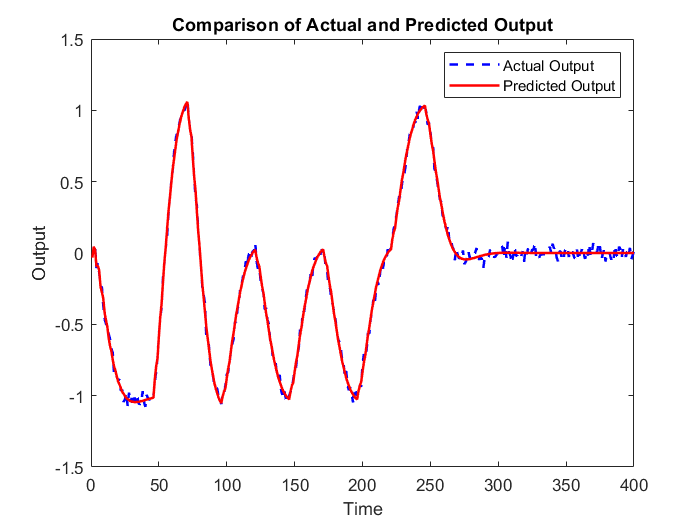

% Plot the actual output and predicted output
figure;
t = 1:length(output3);
plot(t, output3, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)               
  B(z) = 0.06373 z^-2 - 0.02326 z^-3 - 0.004318 z^-4 + 0.008987 z^-5
                                                                    
  F(z) = 1 - 1.051 z^-1 + 0.2205 z^-2 - 0.7406 z^-3 + 0.6166 z^-4   
                                                                    
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   nb=4   nf=4   nk=2
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                
Estimated using OE on time domain data.
Fit to estimation data: 94.1%          
FPE: 0.001008, MSE: 0.0009685          


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

   0.4111 + 0.3732i
   0.4111 - 0.3732i
  -0.4574 + 0.0000i



disp('Poles:');

Poles:


disp(poles_est);

  -0.3751 + 0.7821i
  -0.3751 - 0.7821i
   0.9008 + 0.0905i
   0.9008 - 0.0905i



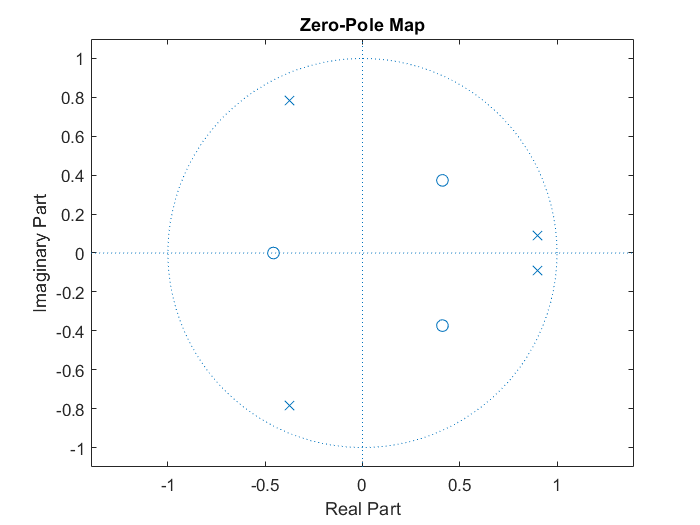


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.6130



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

   -0.3469



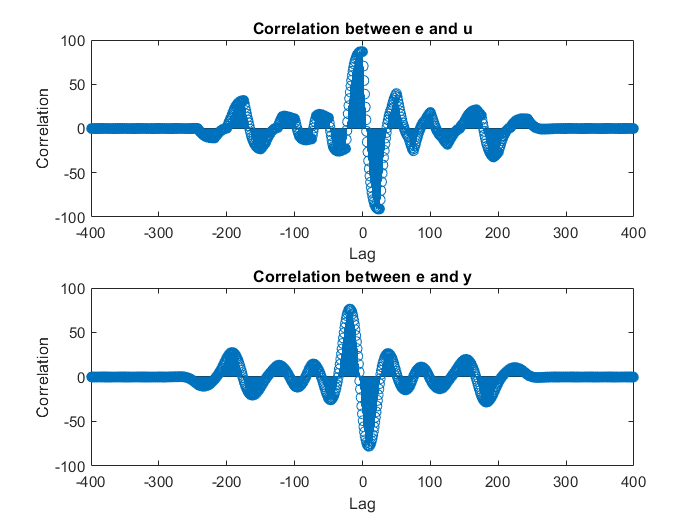


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');

best_y_pred = [];  
best_na = 0;            % Variable to store the best 'na' value
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model
% Loop over each combination of 'nb', 'nf', and 'nk' values
for nb = nb_values
    for nf = nf_values
        for nk = nk_values
            % Output-Error Model Identification
            sys = oe(iddata(output3, u.', 0.01), [nb, 1, nk]);
            sys.Ts = 0.01; 
            y_val_pred = compare(sys, iddata(output3, u.', 0.01));
            val_error = mean((y_val_pred.OutputData - output3).^2);
            if val_error < best_val_error
                best_val_error = val_error;
                best_nb = nb;
                best_nf = nf;
                best_nk = nk;
                best_model = sys;  % Store the best model
                best_y_pred = y_val_pred.OutputData;  
            end
        end
    end
end

% Display the best parameter values and validation error
disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 4


disp(['Best nf value: ', num2str(best_nf)]);

Best nf value: 1


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 4


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.0035754



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: 1
                 B: [0 0 0 0 0.1138 -0.0152 -0.0939 0.1353]
                 C: 1
                 D: 1
                 F: [1 -0.8661]
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 0.0037
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



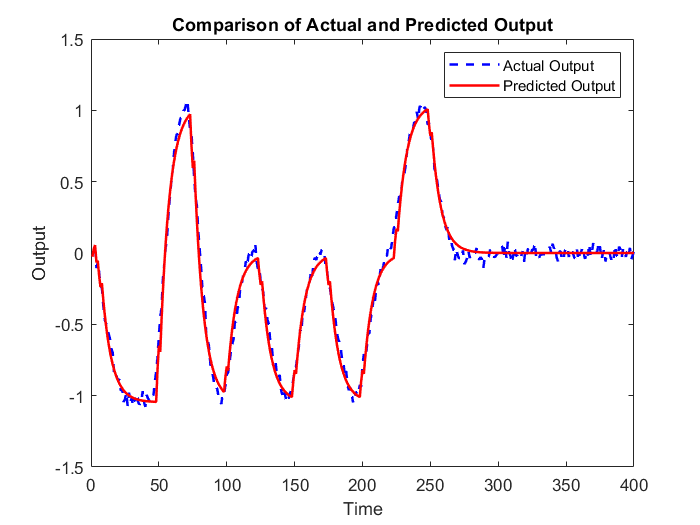

% Plot the actual output and predicted output
figure;
t = 1:length(output3);
plot(t, output3, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)           
  B(z) = 0.1138 z^-4 - 0.01523 z^-5 - 0.09386 z^-6 + 0.1353 z^-7
                                                                
  F(z) = 1 - 0.8661 z^-1                                        
                                                                
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   nb=4   nf=1   nk=4
   Number of free coefficients: 5
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                
Estimated using OE on time domain data.
Fit to estimation data: 88.58%         
FPE: 0.003719, MSE: 0.003628           


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

  -1.2633 + 0.0000i
   0.6986 + 0.6727i
   0.6986 - 0.6727i



disp('Poles:');

Poles:


disp(poles_est);

         0
         0
         0
    0.8661



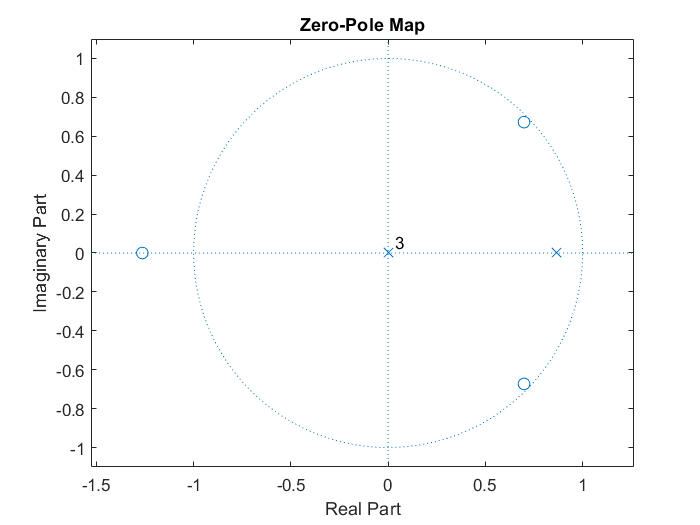


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');